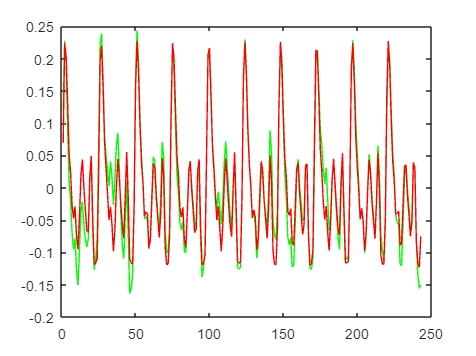

clear
clc

load("Guitar.MAT");
upsample = resample(realwave,10,1); % 对原音频做升采样，变为2430个点
meansample = upsample(1:243); % 将整个时域波形截为10个片段，各片段求平均
for x = [1:9]
    meansample = meansample + upsample(x*243+1:(x+1)*243);
end
meansample = meansample/10;
sample = repmat(meansample,[10,1]);
sample = resample(sample,1,10); % 降采样还原为243个点
plot([1:243],realwave,'green',[1:243],sample,'red');


Fs = 8000; %采样率
L = length(realwave); %信号长度
T = 1/Fs; %采样周期
t = (0:L-1)*T %时间轴

t =          0    0.0001    0.0003    0.0004    0.0005    0.0006    0.0008    0.0009    0.0010    0.0011    0.0013    0.0014    0.0015    0.0016    0.0018    0.0019    0.0020    0.0021    0.0023    0.0024    0.0025    0.0026    0.0027    0.0029    0.0030    0.0031    0.0033    0.0034    0.0035    0.0036    0.0037    0.0039    0.0040    0.0041    0.0043    0.0044    0.0045    0.0046    0.0047    0.0049    0.0050    0.0051    0.0053    0.0054    0.0055    0.0056    0.0057    0.0059    0.0060    0.0061


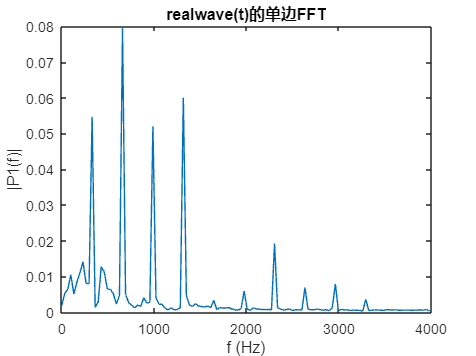

F = fft(realwave);
FP2 = abs(F/L); %计算幅度
FP1 = FP2(1:floor(L/2)+1); %取半边
FP1(2:end-1) = 2*FP1(2:end-1); %除0频其余翻倍
f = Fs*(0:(L/2))/L; %计算对应频率
plot(f,FP1) 
title("realwave(t)的单边FFT")
xlabel("f (Hz)")
ylabel("|P1(f)|")

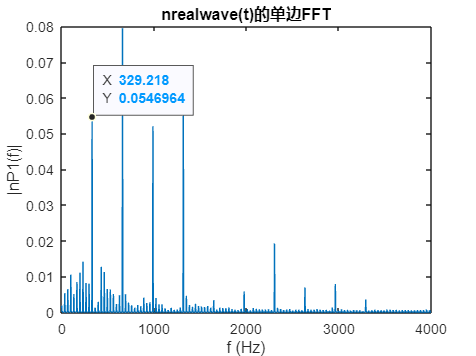


nrealwave = repmat(realwave,[10,1]);
nFs = 8000; %采样率
nL = length(nrealwave); %信号长度
nT = 1/nFs; %采样周期
nt = (0:nL-1)*nT; %时间轴
nF = fft(nrealwave);
nFP2 = abs(nF/nL);
nFP1 = nFP2(1:floor(nL/2)+1);
nFP1(2:end-1) = 2*nFP1(2:end-1);
nf = nFs*(0:(nL/2))/nL;
plot(nf,nFP1) 
title("nrealwave(t)的单边FFT")
xlabel("f (Hz)")
ylabel("|nP1(f)|")
xlim([0 4000])
ylim([0.000 0.080])
ax = gca;
chart = ax.Children(1);
datatip(chart,329.2,0.0547);

% 可见基频为329.218Hz，查表得音调为E4
% 之所以重复会增加信号的频域分辨率，是因为重复后频率分量不改变，
% 但由于主值区间点数N增加，/delta{omega}=2pi/(NTs)变小，频域分辨率提升，原先的连续谱近似变为若干峰值